## a) Igual á b)

## b)

%the probability of the link being in each of the five states;
pi0 = 1/(1+(8/600)+(8/600)*(5/100) + (8/600)*(5/100) * (2/20) + (8/600)*(5/100) * (2/20) * (1/5));
p1 = pi0*(8/600);
p2 = pi0*(8/600)*(5/100) ;
p3 = pi0*(8/600)*(5/100)*(2/20);
p4 = pi0*(8/600)*(5/100)*(2/20)*(1/5);

v = [pi0,p1,p2,p3,p4];

fprintf('valores: \n\t%.2e \n\t%.2e \n\t%.2e \n\t%.2e \n\t%.2e',v)

valores: 
	9.86e-01 
	1.31e-02 
	6.57e-04 
	6.57e-05 
	1.31e-05

## c)

%the average percentage of time the link is in each of the five states;

ber = pi0 * (10^(-6)) + p1 * (10^(-5)) + p2 * (10^(-4)) + p3 * (10^(-3)) +p4 * (10^(-2));

fprintf("ber: %.2e", ber)

ber: 1.38e-06

## d)


% the average holding time (in minutes) of the link in each of the five states;

holding_time = 60.*[1/8 1/(600+5) 1/(100+2) 1/(20+1), 1/5];

fprintf("time: %.1f min %.1f min %.1f min %.1f min %.1f min", holding_time)

time: 7.5 min 0.1 min 0.6 min 2.9 min 12.0 min

## e)

% the probability of the link being in the normal state and in interference state;


probInterference = p4 + p3; % Probability of being in the interference state
probNormal = 1 - probInterference;

fprintf("\nNormal State: %.6f", probNormal);


Normal State: 0.999921

fprintf("\nInterference State: %.2e", probInterference);


Interference State: 7.89e-05

## f)


%the average ber of the link when it is in the normal state and when it is in the interference
%state; answer: 1.18*10^(-6) (normal), 2.50*10^(-3) (interference)

% tenho de fazer uma average wiegh do ber e das respetivas probabilidades

bers = [10^(-6) 10^(-5) 10^(-4) 10^(-3) 10^(-2)]

bers =     0.0000    0.0000    0.0001    0.0010    0.0100


prob_bers = v

prob_bers =     0.9861    0.0131    0.0007    0.0001    0.0000



%normal de -6 a -4, interferencia de -3 a -2
% Calculate the weighted average BER for normal and interference states


averageBerNormal = sum(bers(1:3) .* prob_bers(1:3)) / probNormal ;
averageBerInterference = sum(bers(4:5) .* prob_bers(4:5)) / probInterference ;

fprintf("\nAverage BER (Normal State): %.2e", averageBerNormal);


Average BER (Normal State): 1.18e-06

fprintf("\nAverage BER (Interference State): %.2e", averageBerInterference);


Average BER (Interference State): 2.50e-03

## g)

% considering a data frame of size B (in Bytes) sent by one source station to a destination
% station, draw a plot with the same look as the plot below of the probability of the packet
% being received by the destination station with at least one error as a function of the packet
% size (from 64 Bytes up to 1500 Bytes)

B = 64:1500 % Packet sizes from 64 Bytes to 1500 Bytes

B =     64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84    85    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100   101   102   103   104   105   106   107   108   109   110   111   112   113


## a) Igual á b)

## b)

%the probability of the link being in each of the five states;
pi0 = 1/(1+(8/600)+(8/600)*(5/100) + (8/600)*(5/100) * (2/20) + (8/600)*(5/100) * (2/20) * (1/5));
p1 = pi0*(8/600);
p2 = pi0*(8/600)*(5/100) ;
p3 = pi0*(8/600)*(5/100)*(2/20);
p4 = pi0*(8/600)*(5/100)*(2/20)*(1/5);

v = [pi0,p1,p2,p3,p4];

fprintf('valores: \n\t%.2e \n\t%.2e \n\t%.2e \n\t%.2e \n\t%.2e',v)

valores: 
	9.86e-01 
	1.31e-02 
	6.57e-04 
	6.57e-05 
	1.31e-05

## c)

%the average percentage of time the link is in each of the five states;

ber = pi0 * (10^(-6)) + p1 * (10^(-5)) + p2 * (10^(-4)) + p3 * (10^(-3)) +p4 * (10^(-2));

fprintf("ber: %.2e", ber)

ber: 1.38e-06

## d)


% the average holding time (in minutes) of the link in each of the five states;

holding_time = 60.*[1/8 1/(600+5) 1/(100+2) 1/(20+1), 1/5];

fprintf("time: %.1f min %.1f min %.1f min %.1f min %.1f min", holding_time)

time: 7.5 min 0.1 min 0.6 min 2.9 min 12.0 min

## e)

% the probability of the link being in the normal state and in interference state;


probInterference = p4 + p3; % Probability of being in the interference state
probNormal = 1 - probInterference;

fprintf("\nNormal State: %.6f", probNormal);


Normal State: 0.999921

fprintf("\nInterference State: %.2e", probInterference);


Interference State: 7.89e-05

## f)


%the average ber of the link when it is in the normal state and when it is in the interference
%state; answer: 1.18*10^(-6) (normal), 2.50*10^(-3) (interference)

% tenho de fazer uma average wiegh do ber e das respetivas probabilidades

bers = [10^(-6) 10^(-5) 10^(-4) 10^(-3) 10^(-2)]

bers =     0.0000    0.0000    0.0001    0.0010    0.0100


prob_bers = v

prob_bers =     0.9861    0.0131    0.0007    0.0001    0.0000



%normal de -6 a -4, interferencia de -3 a -2
% Calculate the weighted average BER for normal and interference states


averageBerNormal = sum(bers(1:3) .* prob_bers(1:3)) / probNormal ;
averageBerInterference = sum(bers(4:5) .* prob_bers(4:5)) / probInterference ;

fprintf("\nAverage BER (Normal State): %.2e", averageBerNormal);


Average BER (Normal State): 1.18e-06

fprintf("\nAverage BER (Interference State): %.2e", averageBerInterference);


Average BER (Interference State): 2.50e-03

## g)

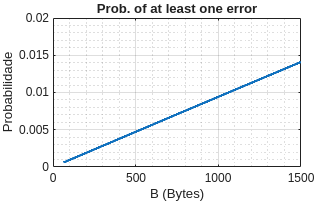

% considering a data frame of size B (in Bytes) sent by one source station to a destination
% station, draw a plot with the same look as the plot below of the probability of the packet
% being received by the destination station with at least one error as a function of the packet
% size (from 64 Bytes up to 1500 Bytes)

% --- 3.g) Probabilidade de Pacote Recebido com Pelo Menos Um Erro ---

% Resultados das alíneas anteriores necessários:
average_ber = 1.38e-6; % Valor do average ber (alínea 3.c)

% 1. Definir o vetor de tamanhos de pacote (Packet Size B) em Bytes
B = 64:1500; 

% 2. Converter o tamanho do pacote B para o número total de bits (N)
N = B * 8; 

% 3. Calcular a probabilidade de ter pelo menos um erro:
% P(>=1 erro) = 1 - P(0 erros) = 1 - (1 - ber)^N

P_at_least_one_error = 1 - (1 - averageBerNormal) .^ N;

%Perguntar ao professor porque é que ele usa o avegaBerNormal em vez de
%apenas o Average Ber

% 4. Plotar os resultados (Escala linear para corresponder ao gráfico de referência)
figure;
plot(B, P_at_least_one_error, '-', 'LineWidth', 2);

% 5. Adicionar rótulos, título e grade
title('Prob. of at least one error');
xlabel('B (Bytes)');
ylabel('Probabilidade');
grid on;
grid minor;

% Ajustar os limites dos eixos para corresponder ao gráfico de referência
xlim([0 1500]);
ylim([0 0.020]);